clc
clear all
clf
addpath("FBA_Lecture/")

Task 1 

                                  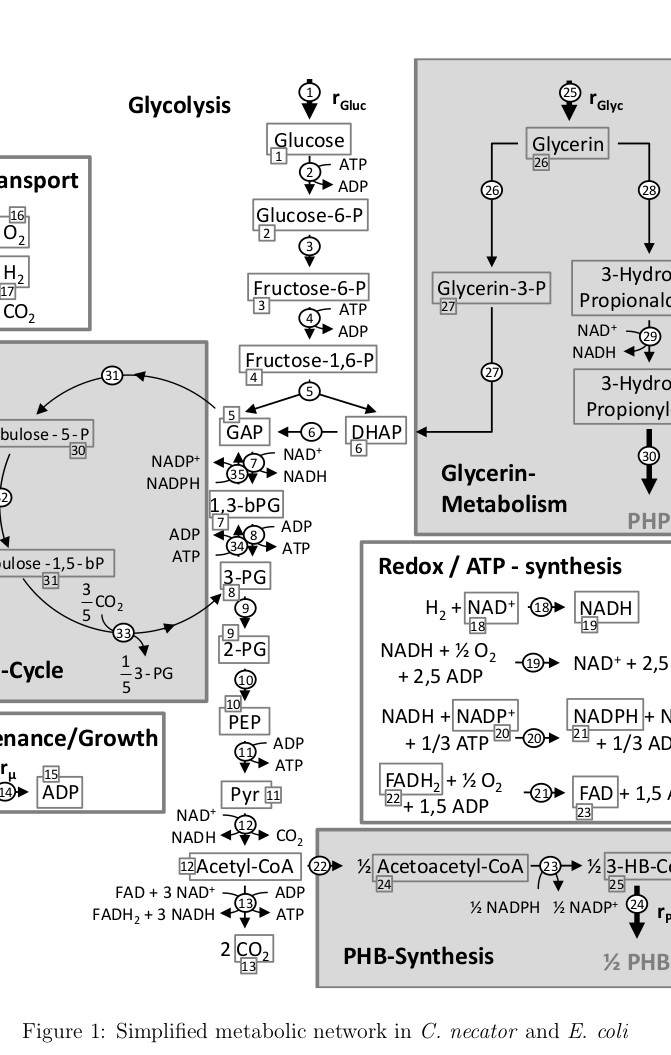

load("FBA_Lecture/N1.mat")


## Checking correctness of the Matrix

%r has to be double from the 6h reaction on
 r = ones(size(N1,2),1)     ;
 r(7:end) = 2               ;
 
 ss = N1*r                  ;
 null(N1)                   ;
 
 

## Increased Comlexity in the Modell 

% Complete glycolysis + redox/ATP + maintenance/growth

2.1  Simulating ATP necessity per mol Glucose, by maximizing ATP consumtion

load('N2') % Complete glycolysis + redox/ATP + maintenance/growth

f = zeros(width(N2),1)  ;       % # entries = # fluxes
f(14) = -1              ;       % Maximization of growth rate (ATP consumption)

b = zeros(height(N2),1) ;       % # entries = # compounds (SS should be fulfilled)

lb = zeros(width(N2),1) ;       % Boundary for fluxes, so # entries = # compounds
lb(17) = -100           ;       % CO2 can be taken up or produced

ub = ones(width(N2),1).*100     ; % Upper boundaries at 100
ub(1)  = 1                      ; % Glucose uptake fixed at 1
ub(16) = 0                      ; % Hydrogen is not considered yet


r_opt = linprog(f,[],[],N2,b,lb,ub) ;

Optimal solution found.



r_mu = r_opt(14);                          
disp([num2str(r_mu),'mol ATP per mole glucose']) 

32mol ATP per mole glucose


2.2  How many moles of glucose are necessary to produce 50 mol atp?

load('N2') % Complete glycolysis + redox/ATP + maintenance/growth

f = zeros(width(N2),1)  ;       % # entries = # fluxes
f(2) = 1              ;         % Minimization of glucose Consumption

b = zeros(height(N2),1) ;       % # entries = # compounds (SS should be fulfilled)

lb = zeros(width(N2),1) ;       % Boundary for fluxes, so # entries = # compounds
lb(14) = 50             ;                      
lb(17) = -100           ;       % CO2 can be taken up or produced

ub = ones(width(N2),1).*100     ; % Upper boundaries at 100
ub(16)  = 0                     ; % Hydrogen is not considered yet


r_opt = linprog(f,[],[],N2,b,lb,ub);

Optimal solution found.



r_mu = r_opt(1);                           % 32 ATP per molecule of glucose
disp([num2str(r_mu),' moles Glucose for 50 mol ATP'])       

1.5625 moles Glucose for 50 mol ATP


## PHB Synthesis 

  Complete glycolysis + redox/ATP + maintenance/growth + PHB 

3.1  How many moles of PHBcan be produced from one mol of glucose?

load('N3') % Complete glycolysis + redox/ATP + maintenance/growth

f = zeros(width(N3),1)  ;       % # entries = # fluxes
f(24) = -1              ;       % Maximization PHB synthetization rate

b = zeros(height(N3),1) ;       % # entries = # compounds (SS should be fulfilled)

lb = zeros(width(N3),1) ;       % Boundary for fluxes, so # entries = # compounds
lb(17) = -100           ;       % CO2 can be taken up or produced

ub = ones(width(N3),1).*100     ; % Upper boundaries at 100
ub(1)  = 1                      ; % Glucose uptake fixed at 1
ub(16) = 0                      ; % Hydrogen is not considered yet

r_opt = linprog(f,[],[],N3,b,lb,ub); 

Optimal solution found.



r_mu = r_opt(24);                 
disp([num2str(r_opt(24)),' moles PHB for 1 mol Glucose'])

1 moles PHB for 1 mol Glucose


disp([num2str(r_opt(14)),' moles ATP for 1 mol Glucose'])

9.1667 moles ATP for 1 mol Glucose


3.2 simultaneously optimizing growthrate and PHB production, 

implementation by introducing weightening factors for both. rphb>rmy

% rPHB is maximized and rµ is minimized

f = zeros(width(N3),1)  ;       % # entries = # fluxes
f(24) = -1              ;       % Maximization PHB synthetization rate
f(14) =  0.01            ;       % Minimized ATP consumption

r_opt = linprog(f,[],[],N3,b,lb,ub); 

Optimal solution found.




disp('rPHB maximized rµ minimized:')

rPHB maximized rµ minimized:


disp([num2str(r_opt(24)),' moles PHB for 1 mol Glucose'])

1 moles PHB for 1 mol Glucose


disp([num2str(r_opt(14)),' moles ATP for 1 mol Glucose'])

9.1667 moles ATP for 1 mol Glucose



% rPHB rµ are maximized

f = zeros(width(N3),1)  ; % # entries = # fluxes
f(24) = -1             ; % Maximization PHB synthetization rate
f(14) = -0.01          ; % Minimized ATP consumption

r_opt = linprog(f,[],[],N3,b,lb,ub); 

Optimal solution found.




disp('rPHB rµ are maximized :')

rPHB rµ are maximized :


disp([num2str(r_opt(24)),' moles PHB for 1 mol Glucose'])

1 moles PHB for 1 mol Glucose


disp([num2str(r_opt(14)),' moles ATP for 1 mol Glucose'])

9.1667 moles ATP for 1 mol Glucose


3.3 Create a pareto front or the multitargetOptimization

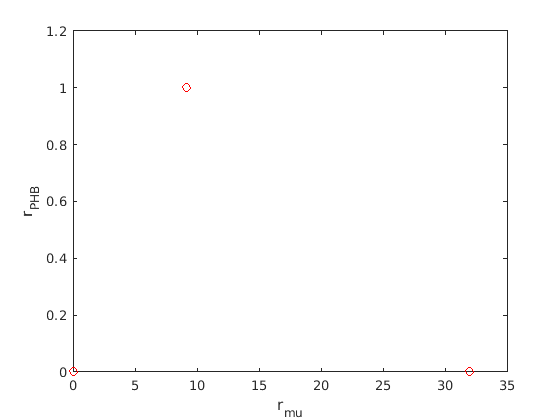

f = zeros(width(N3),1); 
f(24) = -1; % Maximization of PHB production, 1st priority

options = optimoptions('linprog','Display','none');
% Surpresse output message 'Optimal solution found' in linprog

% Pareto front with priority varying
for i=-1:0.005:1
    f(14)=i;
    r_opt = linprog(f,[],[],N3,b,lb,ub,options);
    figure(1)
    plot(r_opt(14),r_opt(24),'ro')
    hold on
end
 
xlabel('r_{mu}');
ylabel('r_{PHB}');